% This is a generic program to generate calibration plot and provide slop
% and intercept data
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Date: August 5th, 2020
% Dr. Vibhav Durgesh
% Rev 0.0
% User has to provide appropriate information - see beginning of code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
close all
clc

## User have to manually add information

x = [1.698 1.4901 1.6923 1.9031]; %Voltage Data
y = [0 9.81 0 -9.81]; % Acceleration
t_nuP= 2.262; % Value read from t-student's table
plotTitle = 'FirstName LastName''s Calibration Plot';

## Performing linear curve fitting

[p,s] = polyfit (x,y,1); % Curve fitting with 1st order fit

## Generating curvefit line

xfit = x;% Generating degree of freedom for the curve fit
yfit = polyval(p,xfit);
nu = s.df; % Getting degree of freedom for the curve fit 
norm = s.normr; % Getting the norm of the curve fitting
syx = norm/sqrt(nu);

## Generating figure with specific size

figure(1)
set(gcf,'unit','inches','position',[0.50 0.50 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data and adding labels

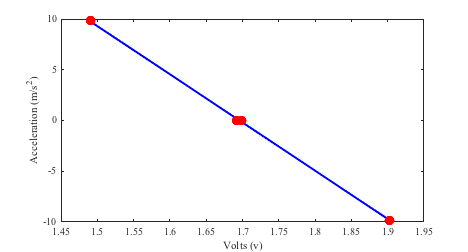

plot(xfit,yfit,'b-','linewidth',2);hold on
plot(x,y,'ro','markersize',9,'markerfacecolor','r')
xlabel('Volts (v)')
ylabel('Acceleration (m/s^{2})')

## Now adding 95% confidence level in the plot

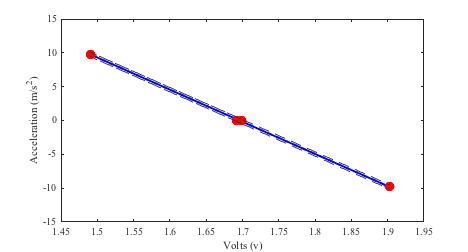

y_cl_low = yfit - t_nuP*syx; % Using regression analysis
y_cl_up  = yfit + t_nuP*syx;
plot(xfit,y_cl_low,'--','color',[0.2 0.2 0.2], 'HandleVisibility','off');
plot(xfit,y_cl_up,'--','color',[0.2 0.2 0.2]);

## Adding confidence level lines on curve fit

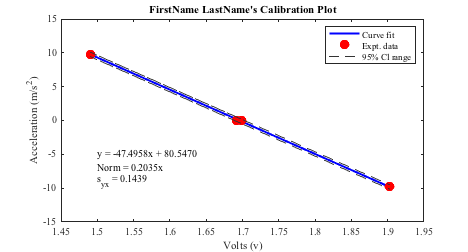

legend('Curve fit','Expt. data','95% Cl range','location','Northeast')
title(plotTitle)
text(1.5,-5,sprintf('y = %3.4fx + %3.4f',p(1),p(2)),'Fontname','times')
text(1.5,-7,sprintf('Norm = %3.4fx',s.normr),'Fontname','times')
text(1.5,-9,sprintf('s_{yx} = %3.4f',syx),'Fontname','times')

## Saving the files in png and pdf format

figName = ['../Figures/Student_Name_Exp03_Part1'];
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'Papersize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')